clear;
clc;
close all;
syms beta(t) beta_dot(t) beta_ddot(t) gamma(t) gamma_dot(t) gamma_ddot(t) x_dist y_dist a b l_2(t) l_3(t) l_dot_2(t) l_ddot_2(t) l_dot_3(t) l_ddot_3(t) J_2 J_3 f_2 f_3
constants = [x_dist, y_dist, a, b];
engine_nadir = rotz(gamma)*roty(beta)*[-a; 0; 0];
l_2_engine_attach = rotz(gamma)*roty(beta)*[-a; 0; b];
l_3_engine_attach = rotz(gamma)*roty(beta)*[-a; b; 0];
l_2_frame_attach = [y_dist; 0; x_dist];
l_3_frame_attach = [y_dist; x_dist; 0];

T_dot = diff(engine_nadir, t);
T_dot = subs(T_dot, [diff(beta, t), diff(gamma, t)], [beta_dot, gamma_dot]);
T_ddot = diff(T_dot, t);
T_ddot = subs(T_ddot, [diff(beta, t), diff(gamma, t), diff(beta_dot, t), diff(gamma_dot, t)], [beta_dot, gamma_dot, beta_ddot, gamma_ddot]);

l_2_vec = l_2_engine_attach - l_2_frame_attach;
l_3_vec = l_3_engine_attach - l_3_frame_attach;

eq_1 = l_2(t)^2 == simplify(expand(subs((l_2_vec)' * l_2_vec, [conj(beta), conj(gamma), conj(a), conj(b), conj(x_dist), conj(y_dist)], [beta, gamma, a, b, x_dist, y_dist])));
eq_2 = l_3(t)^2 == simplify(expand(subs((l_3_vec)' * l_3_vec, [conj(beta), conj(gamma), conj(a), conj(b), conj(x_dist), conj(y_dist)], [beta, gamma, a, b, x_dist, y_dist])));

eq_1 = subs(diff(eq_1, t), [diff(beta, t), diff(gamma, t) diff(l_2, t)], [beta_dot, gamma_dot, l_dot_2]);
eq_2 = subs(diff(eq_2, t), [diff(beta, t), diff(gamma, t) diff(l_3, t)], [beta_dot, gamma_dot, l_dot_3]);

A = -2*a*x_dist*cos(beta) - 2*a*y_dist*sin(beta)*cos(gamma) + 2*b*x_dist*sin(beta) - 2*b*y_dist*cos(beta)*cos(gamma);
B = -2*a*y_dist*cos(beta)*sin(gamma) + 2*b*y_dist*sin(gamma)*sin(beta);
C = -2*a*x_dist*sin(beta)*sin(gamma) - 2*a*y_dist*sin(beta)*cos(gamma);
D = 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma) + 2*b*x_dist*sin(gamma) + 2*b*y_dist*cos(gamma);

eq_3 = beta_dot(t) == (2*l_2*l_dot_2*D - 2*l_3*l_dot_3*B)/(A*D - B*C);
eq_4 = gamma_dot(t) == (2*l_2*l_dot_2*C - 2*l_3*l_dot_3*A)/(B*C - A*D);

eq_3 = subs(diff(eq_3, t), [diff(beta, t), diff(gamma, t), diff(beta_dot, t), diff(gamma_dot, t), diff(l_2, t), diff(l_3, t), diff(l_dot_2, t), diff(l_dot_3, t)], [beta_dot, gamma_dot, beta_ddot, gamma_ddot, l_dot_2, l_dot_3, l_ddot_2, l_ddot_3]);
eq_4 = subs(diff(eq_4, t), [diff(beta, t), diff(gamma, t), diff(beta_dot, t), diff(gamma_dot, t), diff(l_2, t), diff(l_3, t), diff(l_dot_2, t), diff(l_dot_3, t)], [beta_dot, gamma_dot, beta_ddot, gamma_ddot, l_dot_2, l_dot_3, l_ddot_2, l_ddot_3]);

x = [beta(t); gamma(t); beta_dot(t); gamma_dot(t); l_2(t); l_3(t); l_dot_2(t); l_dot_3(t)];
u = [l_ddot_2(t); l_ddot_3(t)];

x_dot = [beta_dot(t); gamma_dot(t); rhs(eq_3); rhs(eq_4); l_dot_2(t); l_dot_3(t); u];

Jx = jacobian(x_dot, x);
Ju = jacobian(x_dot, u);

x_d = 6.5*0.0254;
y_d = 2*0.0254;
a_val = 10.35*0.0254;
b_val = 3.475*0.0254;
beta_crit = 0;
gamma_crit = 0;
consts = [x_d, y_d, a_val, b_val];
actuator_min = 11.64*0.0254;
actuator_max = 13.39*0.0254;
x_crit = [beta_crit; gamma_crit; 0; 0; l_2_length(beta_crit, gamma_crit, x_d, y_d, a_val, b_val); l_3_length(beta_crit, gamma_crit, x_d, y_d, a_val, b_val); 0; 0];
u_crit = [1e-1; 1e-1];
state_limits = [    -pi/12,         pi/12;
                    -pi/12,         pi/12;
                    -100,           100;
                    -100,           100;
                    actuator_min,   actuator_max;
                    actuator_min,   actuator_max;
                    -100,           100;
                    -100,           100              ];
input_limits = [    -200,           200;
                    -200,           200               ];

A = double(subs(Jx, [beta(t), gamma(t), beta_dot(t), gamma_dot(t), l_2(t), l_3(t), l_dot_2(t), l_dot_3(t), l_ddot_2(t), l_ddot_3(t), constants], [x_crit', u_crit', consts]));
B = double(subs(Ju, [beta(t), gamma(t), beta_dot(t), gamma_dot(t), l_2(t), l_3(t), l_dot_2(t), l_dot_3(t), l_ddot_2(t), l_ddot_3(t), constants], [x_crit', u_crit', consts]));

uncontrollable_states = length(A) - rank(ctrb(A, B));

Q = diag([pi/1200, pi/1200, 1, 1, 1, 1, 1, 1].^(-2));
R = eye(size(B, 2));

[K, ~, ~] = lqr(A, B, Q, R);

beta_0 = 0;
gamma_0 = 0;
x_0 = [beta_0; gamma_0; 0; 0; l_2_length(beta_0, gamma_0, x_d, y_d, a_val, b_val); l_3_length(beta_0, gamma_0, x_d, y_d, a_val, b_val); 0; 0];
time = linspace(0, 10, 500)';
beta_ref = (pi/12)*cos(2*pi*time/time(end));
gamma_ref = (pi/12)*sin(2*pi*time/time(end));
% beta_ref = [linspace(-pi/12, pi/12, length(time)/4)'; pi*ones(length(time)/4, 1)/12; linspace(pi/12, -pi/12, length(time)/4)'; -pi*ones(length(time)/4, 1)/12];
% gamma_ref = [pi*ones(length(time)/4, 1)/12; linspace(pi/12, -pi/12, length(time)/4)'; -pi*ones(length(time)/4, 1)/12; linspace(-pi/12, pi/12, length(time)/4)'];
beta_dot_ref = gradient(beta_ref);
gamma_dot_ref = gradient(gamma_ref);
l_2_ref = l_2_length(beta_ref, gamma_ref, x_d, y_d, a_val, b_val);
l_3_ref = l_3_length(beta_ref, gamma_ref, x_d, y_d, a_val, b_val);
l_dot_2_ref = gradient(l_2_ref);
l_dot_3_ref = gradient(l_3_ref);
x_ref = [time, beta_ref, gamma_ref, beta_dot_ref, gamma_dot_ref, l_2_ref, l_3_ref, l_dot_2_ref, l_dot_3_ref];
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
[time, x_set] = ode45(@(t, x) deriv(t, x, x_ref, K, consts, state_limits, input_limits), time, x_0, opts);

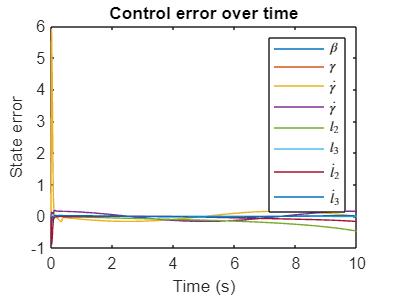

figure;
plot(time, x_set - x_ref(:, 2:end));
title("Control error over time");
xlabel("Time (s)");
ylabel("State error");
legend("$\beta$", "$\gamma$", "$\dot{\gamma}$", "$\dot{\gamma}$", "$l_2$", "$l_3$", "$\dot{l}_2$", "$\dot{l}_3$", 'Interpreter', "latex");

% close all;
% figure; hold on
% title(sprintf("TVC\nTime: %0.2f sec", time(1)), 'Interpreter', 'latex');
% xlabel("$\hat{\mathbf{b}}_2$", 'Interpreter', 'latex');
% ylabel("$\hat{\mathbf{b}}_3$", 'Interpreter', 'latex');
% zlabel("$\hat{\mathbf{b}}_1$", 'Interpreter', 'latex');
% grid minor;
% axis equal;
% view(-45,30);
% 
% filename = 'tvc_animation.gif';
% 
% center_plot = plot3(0, 0, 0, 'ko', 'MarkerFaceColor', [0, 0, 0]);
% 
% nadir_point = get_nadir(x_set(1, 1), x_set(1, 2), a_val, b_val);
% nadir_plot = plot3([0, nadir_point(2)], [0, nadir_point(3)], [0, nadir_point(1)], 'k-', 'LineWidth', 2.5);
% 
% l_2_engine_point = get_l_2_attachment(x_set(1, 1), x_set(1, 2), a_val, b_val);
% l_2_engine_mount_plot = plot3([nadir_point(2), l_2_engine_point(2)], [nadir_point(3), l_2_engine_point(3)], [nadir_point(1), l_2_engine_point(1)], 'k-', 'LineWidth', 2.5);
% 
% l_3_engine_point = get_l_3_attachment(x_set(1, 1), x_set(1, 2), a_val, b_val);
% l_3_engine_mount_plot = plot3([nadir_point(2), l_3_engine_point(2)], [nadir_point(3), l_3_engine_point(3)], [nadir_point(1), l_3_engine_point(1)], 'k-', 'LineWidth', 2.5);
% 
% l_2_frame_point = double(subs(l_2_frame_attach, [beta(t), gamma(t), constants], [x_set(1, 1), x_set(1, 2), consts]));
% l_2_frame_mount_plot = plot3(l_2_frame_point(2), l_2_frame_point(3), l_2_frame_point(1), 'bo', 'MarkerFaceColor', [0, 0, 1]);
% l_2_actuator_plot = plot3([l_2_engine_point(2), l_2_frame_point(2)], [l_2_engine_point(3), l_2_frame_point(3)], [l_2_engine_point(1), l_2_frame_point(1)], 'b-', 'LineWidth', 4);
% 
% l_3_frame_point = double(subs(l_3_frame_attach, [beta(t), gamma(t), constants], [x_set(1, 1), x_set(1, 2), consts]));
% l_3_frame_mount_plot = plot3(l_3_frame_point(2), l_3_frame_point(3), l_3_frame_point(1), 'ro', 'MarkerFaceColor', [1, 0, 0]);
% l_3_actuator_plot = plot3([l_3_engine_point(2), l_3_frame_point(2)], [l_3_engine_point(3), l_3_frame_point(3)], [l_3_engine_point(1), l_3_frame_point(1)], 'r-', 'LineWidth', 4);
% 
% nadir_history = plot3(nadir_point(2), nadir_point(3), nadir_point(1), 'go', 'MarkerFaceColor', [0 .75 0], 'MarkerSize', 2);
% 
% for k = 1:length(time)
%     nadir_point = get_nadir(x_set(k, 1), x_set(k, 2), a_val, b_val);
%     plot3(nadir_point(2), nadir_point(3), nadir_point(1), 'Color', 'none');
% 
%     l_2_engine_point = get_l_2_attachment(x_set(k, 1), x_set(k, 2), a_val, b_val);
%     plot3([nadir_point(2), l_2_engine_point(2)], [nadir_point(3), l_2_engine_point(3)], [nadir_point(1), l_2_engine_point(1)], 'Color', 'none');
% 
%     l_3_engine_point = get_l_3_attachment(x_set(k, 1), x_set(k, 2), a_val, b_val);
%     plot3([nadir_point(2), l_3_engine_point(2)], [nadir_point(3), l_3_engine_point(3)], [nadir_point(1), l_3_engine_point(1)], 'Color', 'none');
% 
%     plot3([l_2_engine_point(2), l_2_frame_point(2)], [l_2_engine_point(3), l_2_frame_point(3)], [l_2_engine_point(1), l_2_frame_point(1)], 'Color', 'none');
% 
%     plot3([l_3_engine_point(2), l_3_frame_point(2)], [l_3_engine_point(3), l_3_frame_point(3)], [l_3_engine_point(1), l_3_frame_point(1)], 'Color', 'none');
% end
% for k = 1:length(time)
%     nadir_point = get_nadir(x_set(k, 1), x_set(k, 2), a_val, b_val);
%     nadir_plot.XData = [0, nadir_point(2)];
%     nadir_plot.YData = [0, nadir_point(3)];
%     nadir_plot.ZData = [0, nadir_point(1)];
% 
%     l_2_engine_point = get_l_2_attachment(x_set(k, 1), x_set(k, 2), a_val, b_val);
%     l_2_engine_mount_plot.XData = [nadir_point(2), l_2_engine_point(2)];
%     l_2_engine_mount_plot.YData = [nadir_point(3), l_2_engine_point(3)];
%     l_2_engine_mount_plot.ZData = [nadir_point(1), l_2_engine_point(1)];
% 
%     l_3_engine_point = get_l_3_attachment(x_set(k, 1), x_set(k, 2), a_val, b_val);
%     l_3_engine_mount_plot.XData = [nadir_point(2), l_3_engine_point(2)];
%     l_3_engine_mount_plot.YData = [nadir_point(3), l_3_engine_point(3)];
%     l_3_engine_mount_plot.ZData = [nadir_point(1), l_3_engine_point(1)];
% 
%     l_2_actuator_plot.XData = [l_2_engine_point(2), l_2_frame_point(2)];
%     l_2_actuator_plot.YData = [l_2_engine_point(3), l_2_frame_point(3)];
%     l_2_actuator_plot.ZData = [l_2_engine_point(1), l_2_frame_point(1)];
% 
%     l_3_actuator_plot.XData = [l_3_engine_point(2), l_3_frame_point(2)];
%     l_3_actuator_plot.YData = [l_3_engine_point(3), l_3_frame_point(3)];
%     l_3_actuator_plot.ZData = [l_3_engine_point(1), l_3_frame_point(1)];
% 
%     nadir_history.XData = [nadir_history.XData, nadir_point(2)];
%     nadir_history.YData = [nadir_history.YData, nadir_point(3)];
%     nadir_history.ZData = [nadir_history.ZData, nadir_point(1)];
% 
%     title(sprintf("TVC\nTime: %0.2f sec", time(k)), 'Interpreter', 'latex');
%     pause(.1*time(end)/length(time));
%     drawnow limitrate
% end
% drawnow

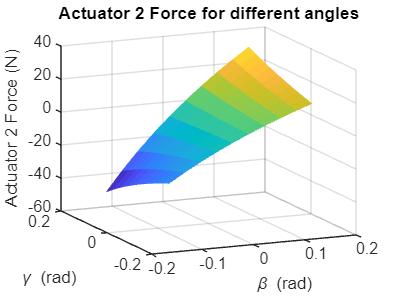

syms F_2 F_3
m_e = 20*0.453592;
l_e = a_val*0.8;
g = 9.81;

F_2_vec = simplify(F_2 * l_2_vec / norm(l_2_vec, 2));
F_3_vec = simplify(F_3 * l_3_vec / norm(l_3_vec, 2));
W_e = [0; -m_e*g; 0];
l_eg = simplify(l_e * engine_nadir / norm(engine_nadir, 2));
T_eg = simplify(cross(l_eg, W_e));
T_2 = simplify(cross(engine_nadir, F_2_vec));
T_3 = simplify(cross(engine_nadir, F_3_vec));
eq_5 = formula(0 == simplify(T_2 + T_3 + T_eg));

beta_list = linspace(deg2rad(-8), deg2rad(8), 10)';
gamma_list = linspace(deg2rad(-8), deg2rad(8), 10)';
[beta_list, gamma_list] = ndgrid(beta_list, gamma_list);
eq_6 = formula(subs(eq_5(2), [a, b, x_dist, y_dist], [a_val, b_val, x_d, y_d]));
eq_7 = formula(subs(eq_5(3), [a, b, x_dist, y_dist], [a_val, b_val, x_d, y_d]));
F_2_sol = zeros(size(beta_list));
F_3_sol = zeros(size(gamma_list));
for i = 1:numel(beta_list)
    eq_8 = formula(subs(eq_6, [beta(t), gamma(t)], [beta_list(i), gamma_list(i)]));
    eq_9 = formula(subs(eq_7, [beta(t), gamma(t)], [beta_list(i), gamma_list(i)]));
    [F_2_sol(i), F_3_sol(i)] = solve([eq_8, eq_9], [F_2, F_3]);
end
F_2_list = double(F_2_sol);
F_3_list = double(F_3_sol);

figure;
s0 = surf(beta_list, gamma_list, F_2_list);
xlabel('\beta (rad)');
ylabel('\gamma (rad)');
zlabel('Actuator 2 Force (N)');
title("Actuator 2 Force for different angles");
s0.EdgeColor = 'none';

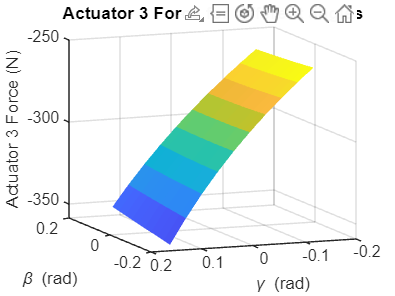


figure;
s1 = surf(beta_list, gamma_list, F_3_list);
xlabel('\beta (rad)');
ylabel('\gamma (rad)');
zlabel('Actuator 3 Force (N)');
title("Actuator 3 Force for different angles");
s1.EdgeColor = 'none';

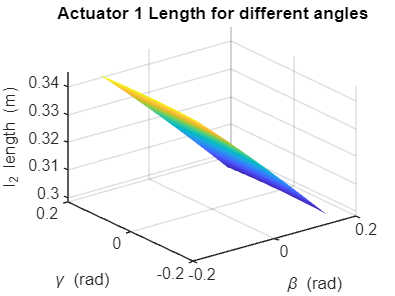

beta_grid = linspace(deg2rad(-9), deg2rad(9), 1000);
gamma_grid = linspace(deg2rad(-9), deg2rad(9), 1000);
[beta_grid, gamma_grid] = ndgrid(beta_grid, gamma_grid);
l_2_grid = zeros(size(beta_grid));
l_3_grid = zeros(size(beta_grid));
for i = 1:numel(l_2_grid)
    l_2_grid(i) = l_2_length(beta_grid(i), gamma_grid(i), x_d, y_d, a_val, b_val);
    l_3_grid(i) = l_3_length(beta_grid(i), gamma_grid(i), x_d, y_d, a_val, b_val);
end

figure;
s2 = surf(beta_grid, gamma_grid, l_2_grid);
xlabel('\beta (rad)');
ylabel('\gamma (rad)');
zlabel('l_2 length (m)');
title("Actuator 1 Length for different angles");
s2.EdgeColor = 'none';

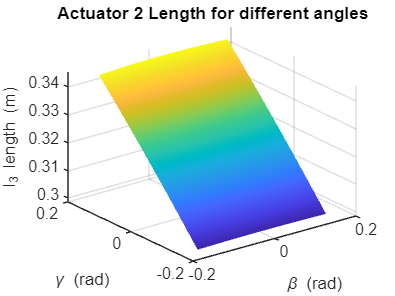


figure;
s3 = surf(beta_grid, gamma_grid, l_3_grid);
xlabel('\beta (rad)');
ylabel('\gamma (rad)');
zlabel('l_3 length (m)');
title("Actuator 2 Length for different angles");
s3.EdgeColor = 'none';

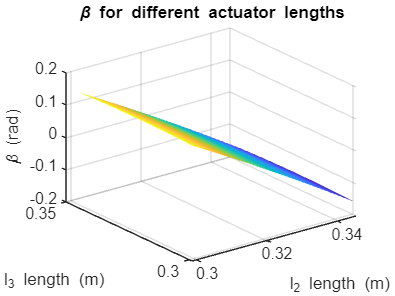


figure;
s4 = surf(l_2_grid, l_3_grid, beta_grid);
xlabel('l_2 length (m)');
ylabel('l_3 length (m)');
zlabel('\beta (rad)');
title("\beta for different actuator lengths");
s4.EdgeColor = 'none';

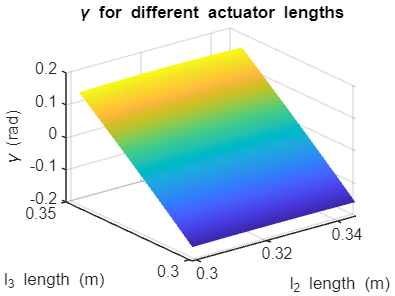


figure;
s5 = surf(l_2_grid, l_3_grid, gamma_grid);
xlabel('l_2 length (m)');
ylabel('l_3 length (m)');
zlabel('\gamma (rad)');
title("\gamma for different actuator lengths");
s5.EdgeColor = 'none';

function mat = rotx(t)
    mat = [1 0 0; 0 cos(t) -sin(t); 0 sin(t) cos(t)];
end

function mat = roty(t)
    mat = [cos(t) 0 sin(t); 0 1 0; -sin(t) 0 cos(t)];
end

function mat = rotz(t)
    mat = [cos(t) -sin(t) 0; sin(t) cos(t) 0; 0 0 1];
end

function l_2 = l_2_length(beta, gamma, x_dist, y_dist, a, b)
    l_2 = sqrt(a^2 - 2*sin(beta)*a*x_dist + 2*cos(beta).*cos(gamma)*a*y_dist + b^2 - 2*cos(beta)*b*x_dist - 2*cos(gamma).*sin(beta)*b*y_dist + x_dist^2 + y_dist^2);
end

function l_3 = l_3_length(beta, gamma, x_dist, y_dist, a, b)
    l_3 = sqrt(a^2 + 2*cos(beta).*sin(gamma)*a*x_dist + 2*cos(beta).*cos(gamma)*a*y_dist + b^2 - 2*cos(gamma)*b*x_dist + 2*sin(gamma)*b*y_dist + x_dist^2 + y_dist^2);
end

function x_dot = deriv(t, x, x_ref, K, constants, state_limits, input_limits)
    for i = 1:length(x)
        x(i) = max(state_limits(i, 1), min(state_limits(i, 2), x(i)));
    end
    
    beta = x(1);
    gamma = x(2);
    beta_dot = x(3);
    gamma_dot = x(4);
    l_2 = x(5);
    l_3 = x(6);
    l_dot_2 = x(7);
    l_dot_3 = x(8);
    
    x_ref_vec = zeros(length(x), 1);
    for i = 1:length(x)
        x_ref_vec(i) = interp1(x_ref(:, 1), x_ref(:, i+1), t);
    end
    u = -K*(x - x_ref_vec);
    for i = 1:length(u)
        u(i) = max(input_limits(i, 1), min(input_limits(i, 2), u(i)));
    end
    
    l_ddot_2 = u(1);
    l_ddot_3 = u(2);

    x_dist = constants(1);
    y_dist = constants(2);
    a = constants(3);
    b = constants(4);

    x_dot = [beta_dot; gamma_dot; - (2*l_dot_2^2*(2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma)) + 2*l_dot_3^2*(2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma)) + 2*l_3*l_ddot_3*(2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma)) - 2*l_2*l_dot_2*(2*b*y_dist*sin(gamma)*gamma_dot - 2*b*x_dist*cos(gamma)*gamma_dot + 2*a*y_dist*cos(beta)*cos(gamma)*gamma_dot + 2*a*x_dist*cos(gamma)*sin(beta)*beta_dot + 2*a*x_dist*cos(beta)*sin(gamma)*gamma_dot - 2*a*y_dist*sin(beta)*sin(gamma)*beta_dot) - 2*l_3*l_dot_3*(2*b*y_dist*cos(beta)*sin(gamma)*beta_dot - 2*a*y_dist*cos(beta)*cos(gamma)*gamma_dot + 2*b*y_dist*cos(gamma)*sin(beta)*gamma_dot + 2*a*y_dist*sin(beta)*sin(gamma)*beta_dot) + 2*l_2*l_ddot_2*(2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma)))/((2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta))*(2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma)) + (2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma))*(2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma))) - ((2*l_3*l_dot_3*(2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma)) + 2*l_2*l_dot_2*(2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma)))*((2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma))*(2*b*y_dist*cos(beta)*sin(gamma)*beta_dot - 2*a*y_dist*cos(beta)*cos(gamma)*gamma_dot + 2*b*y_dist*cos(gamma)*sin(beta)*gamma_dot + 2*a*y_dist*sin(beta)*sin(gamma)*beta_dot) - (2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma))*(2*a*y_dist*cos(beta)*cos(gamma)*beta_dot + 2*a*x_dist*cos(beta)*sin(gamma)*beta_dot + 2*a*x_dist*cos(gamma)*sin(beta)*gamma_dot - 2*a*y_dist*sin(beta)*sin(gamma)*gamma_dot) + (2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma))*(2*b*x_dist*cos(beta)*beta_dot + 2*a*x_dist*sin(beta)*beta_dot - 2*a*y_dist*cos(beta)*cos(gamma)*beta_dot + 2*b*y_dist*cos(gamma)*sin(beta)*beta_dot + 2*b*y_dist*cos(beta)*sin(gamma)*gamma_dot + 2*a*y_dist*sin(beta)*sin(gamma)*gamma_dot) + (2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta))*(2*b*y_dist*sin(gamma)*gamma_dot - 2*b*x_dist*cos(gamma)*gamma_dot + 2*a*y_dist*cos(beta)*cos(gamma)*gamma_dot + 2*a*x_dist*cos(gamma)*sin(beta)*beta_dot + 2*a*x_dist*cos(beta)*sin(gamma)*gamma_dot - 2*a*y_dist*sin(beta)*sin(gamma)*beta_dot)))/((2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta))*(2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma)) + (2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma))*(2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma)))^2; - (2*l_dot_2^2*(2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma)) - 2*l_dot_3^2*(2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta)) + 2*l_2*l_ddot_2*(2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma)) + 2*l_3*l_dot_3*(2*b*x_dist*cos(beta)*beta_dot + 2*a*x_dist*sin(beta)*beta_dot - 2*a*y_dist*cos(beta)*cos(gamma)*beta_dot + 2*b*y_dist*cos(gamma)*sin(beta)*beta_dot + 2*b*y_dist*cos(beta)*sin(gamma)*gamma_dot + 2*a*y_dist*sin(beta)*sin(gamma)*gamma_dot) + 2*l_2*l_dot_2*(2*a*y_dist*cos(beta)*cos(gamma)*beta_dot + 2*a*x_dist*cos(beta)*sin(gamma)*beta_dot + 2*a*x_dist*cos(gamma)*sin(beta)*gamma_dot - 2*a*y_dist*sin(beta)*sin(gamma)*gamma_dot) - 2*l_3*l_ddot_3*(2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta)))/((2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta))*(2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma)) + (2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma))*(2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma))) - ((2*l_2*l_dot_2*(2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma)) - 2*l_3*l_dot_3*(2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta)))*((2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma))*(2*b*y_dist*cos(beta)*sin(gamma)*beta_dot - 2*a*y_dist*cos(beta)*cos(gamma)*gamma_dot + 2*b*y_dist*cos(gamma)*sin(beta)*gamma_dot + 2*a*y_dist*sin(beta)*sin(gamma)*beta_dot) - (2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma))*(2*a*y_dist*cos(beta)*cos(gamma)*beta_dot + 2*a*x_dist*cos(beta)*sin(gamma)*beta_dot + 2*a*x_dist*cos(gamma)*sin(beta)*gamma_dot - 2*a*y_dist*sin(beta)*sin(gamma)*gamma_dot) + (2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma))*(2*b*x_dist*cos(beta)*beta_dot + 2*a*x_dist*sin(beta)*beta_dot - 2*a*y_dist*cos(beta)*cos(gamma)*beta_dot + 2*b*y_dist*cos(gamma)*sin(beta)*beta_dot + 2*b*y_dist*cos(beta)*sin(gamma)*gamma_dot + 2*a*y_dist*sin(beta)*sin(gamma)*gamma_dot) + (2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta))*(2*b*y_dist*sin(gamma)*gamma_dot - 2*b*x_dist*cos(gamma)*gamma_dot + 2*a*y_dist*cos(beta)*cos(gamma)*gamma_dot + 2*a*x_dist*cos(gamma)*sin(beta)*beta_dot + 2*a*x_dist*cos(beta)*sin(gamma)*gamma_dot - 2*a*y_dist*sin(beta)*sin(gamma)*beta_dot)))/((2*a*x_dist*cos(beta) - 2*b*x_dist*sin(beta) + 2*b*y_dist*cos(beta)*cos(gamma) + 2*a*y_dist*cos(gamma)*sin(beta))*(2*b*y_dist*cos(gamma) + 2*b*x_dist*sin(gamma) + 2*a*x_dist*cos(beta)*cos(gamma) - 2*a*y_dist*cos(beta)*sin(gamma)) + (2*a*y_dist*cos(gamma)*sin(beta) + 2*a*x_dist*sin(beta)*sin(gamma))*(2*a*y_dist*cos(beta)*sin(gamma) - 2*b*y_dist*sin(beta)*sin(gamma)))^2; l_dot_2; l_dot_3; l_ddot_2; l_ddot_3];
end

function vec = get_nadir(beta, gamma, a, ~)
    vec = [-a*cos(beta)*cos(gamma); -a*cos(beta)*sin(gamma); a*sin(beta)];
end

function vec = get_l_2_attachment(beta, gamma, a, b)
    vec = [b*cos(gamma)*sin(beta) - a*cos(beta)*cos(gamma); b*sin(beta)*sin(gamma) - a*cos(beta)*sin(gamma); a*sin(beta) + b*cos(beta)];
end

function vec = get_l_3_attachment(beta, gamma, a, b)
    vec = [- b*sin(gamma) - a*cos(beta)*cos(gamma); b*cos(gamma) - a*cos(beta)*sin(gamma); a*sin(beta)];
end